# Explicação do funcionamento das funcões

Primeiro lemos a 

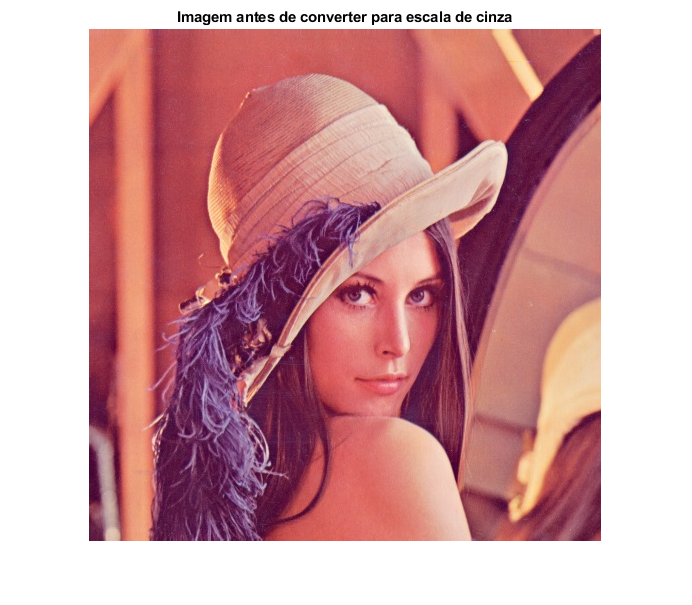

X = imread("Lenna.jpg");
imshow(X);title("Imagem antes de converter para escala de cinza");

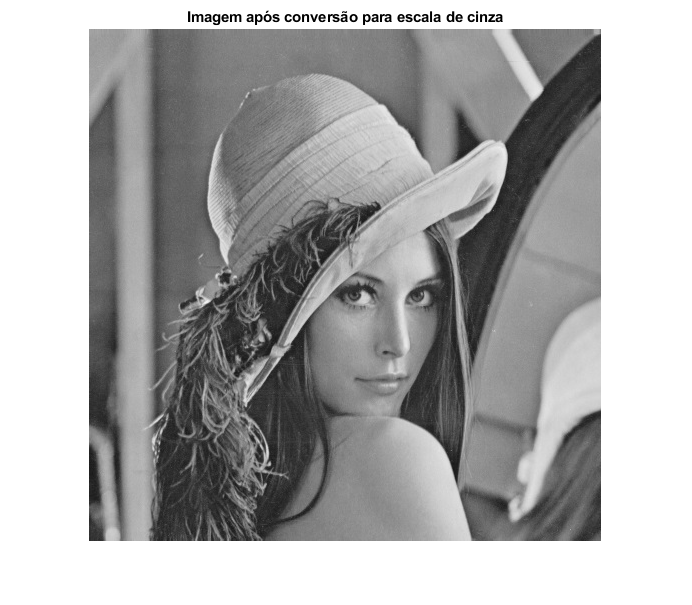

X = double(rgb2gray(X))/255;
imshow(X);title("Imagem após conversão para escala de cinza");

## Procedimentos para comprimir imagem

X_dct = dct2(X);
X_dct_modif = zeros(size(X_dct));
[L,C] = size(X_dct);
partial_dim = 0.05;
L_final = round(partial_dim*L) ; C_final = round(partial_dim*C);
X_dct_modif(1:L_final,1:C_final) = X_dct(1:L_final,1:C_final);

## Procedimentos para recuperar imagem

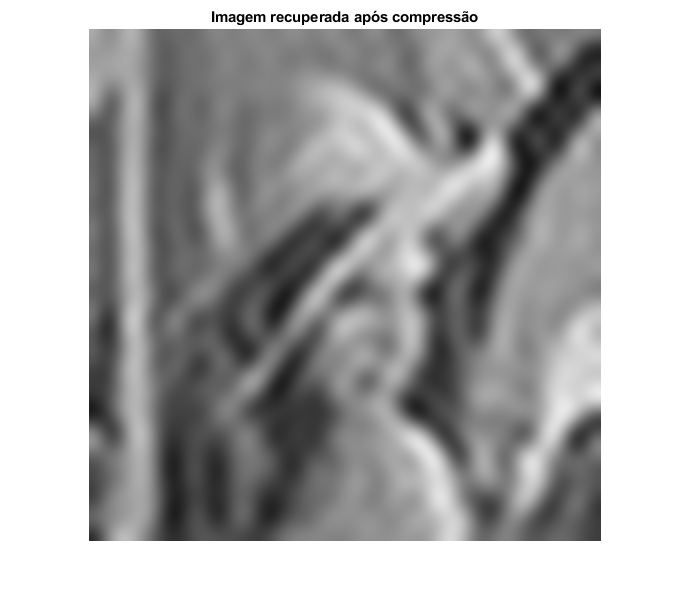

qtd_coeficientes = L_final*C_final;
fator_compressao = 1 - qtd_coeficientes/(L*C);
X_modif = idct2(X_dct_modif);
imshow(X_modif);title("Imagem recuperada após compressão");

Após a compressão com taxa de 99%,na recuperação foi possível notar que a imagem está bem borrada, mas caso se saiba qual é a imagem original então será possível encontrar semelhança.

## Relação sinal ruído de pico da imagem

Valores de erro quadrático médio e relação sinal ruído de pico, respectivamente: 

[L,C] = size(X);
num = 0;
den = 0;
for i = 1 : L
    for j = 1 : C 
        num = num + (X(i,j)-X_modif(i,j))^2;
        den = den + (X(i,j))^2;
    end
end
MSE = num / den;
PSNR_db = 10*log10(65025/MSE);